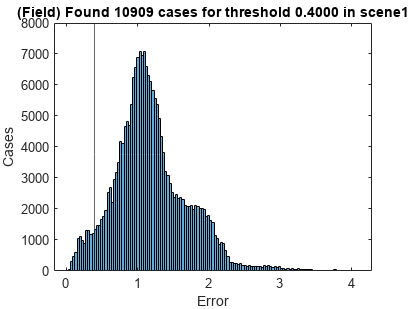

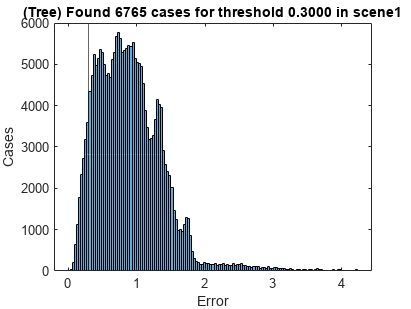

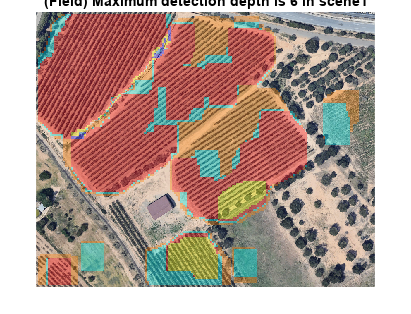

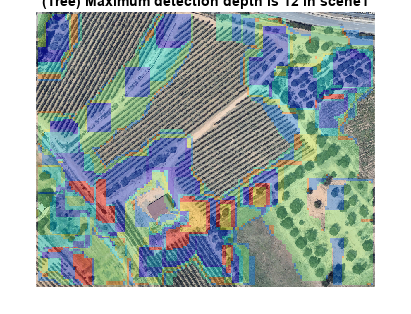

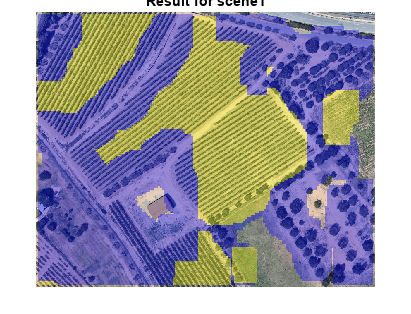

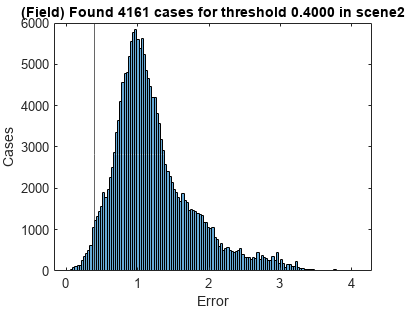

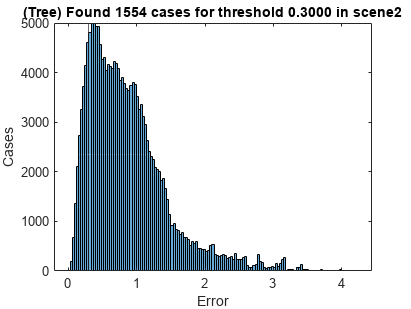

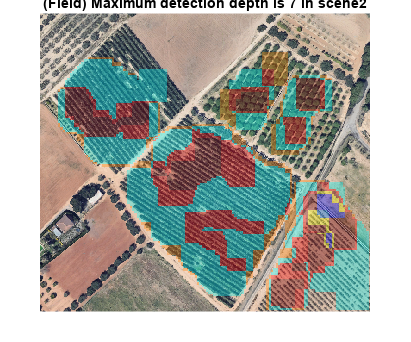

% Classificació
% Netejar l'entorn
clc;
close all;
clear variables;

% Parameters
% Sample settings
sampleFolderPathField = 'imatges/camps'; % For now using 40x40 sample images
sampleFolderPathTree = 'imatges/arbrets'; % For now using 40x40 sample images
sampleRot = 2; % Number of rotations to compute (1 - 4)

% Co-matrix settings
cmHSV = false; % If true, use saturation instead of grayscale
cmGF = 1.5; % Apply Gaussian blur to sample and scene
cmGL = 5; % Gray levels 
cmDist = 2;
cmDir = [0 1; 1 0];% 1 1; -1 1];
%cmDir = [ 1 1; -1 1];
%cmDir = [ 0 1; -1 1];
cmSym = true; % Symmetric (offsets [1 0] == [-1 0])
cmProps = {"Contrast", "Correlation", "Energy", "Homogeneity"};

% Sliding Window settings
swStep = 5;

% Classification settings
classWeight = 0.5; % Classification bias (0 Field always wins, 1 Tree always wins)
%Field
nbestField = 0; % Show best nbest cases. If 0, show cases better than threshold.
thrField = 0.4;
%Tree
nbestTree = 0; % Show best nbest cases. If 0, show cases better than threshold.
thrTree = 0.3;

% Presentation settings
maskAlpha = 0.65;

% Load sample filepaths
% Fields
sampleImdsField = imageDatastore(sampleFolderPathField);
sampleFilesField = size(sampleImdsField.Files, 1);
sampleCasesField = sampleFilesField * sampleRot;

% Tree
sampleImdsTree = imageDatastore(sampleFolderPathTree);
sampleFilesTree = size(sampleImdsTree.Files, 1);
sampleCasesTree = sampleFilesTree * sampleRot;

% Processem la mostra
% Field
samplePropsField = NaN(size(cmProps, 2), size(cmDir, 1), sampleCasesField);
for sf = 1:sampleFilesField
    sampleImg = readimage(sampleImdsField, sf);
    if cmHSV == false
        sampleImg2 = im2gray(sampleImg);
    else
        sampleImg2 = rgb2hsv(sampleImg);
        sampleImg2 = sampleImg2(:,:,1); % Hue
    end
    if cmGF ~= 0
        sampleImg2 = imgaussfilt(sampleImg2, cmGF);
    end
    for rot = 1:sampleRot
        sampleImg2Rot = rot90(sampleImg2, rot-1);
        samplePropsField(:, :, (sf-1)*sampleRot+rot) = extractFeaturesGLCM(sampleImg2Rot, cmDir*cmDist, cmSym, cmProps, cmGL);
    end
end

% Tree
samplePropsTree = NaN(size(cmProps, 2), size(cmDir, 1), sampleCasesTree);
for sf = 1:sampleFilesTree
    sampleImg = readimage(sampleImdsTree, sf);
    if cmHSV == false
        sampleImg2 = im2gray(sampleImg);
    else
        sampleImg2 = rgb2hsv(sampleImg);
        sampleImg2 = sampleImg2(:,:,1); % Hue
    end
    if cmGF ~= 0
        sampleImg2 = imgaussfilt(sampleImg2, cmGF);
    end
    for rot = 1:sampleRot
        sampleImg2Rot = rot90(sampleImg2, rot-1);
        samplePropsTree(:, :, (sf-1)*sampleRot+rot) = extractFeaturesGLCM(sampleImg2Rot, cmDir*cmDist, cmSym, cmProps, cmGL);
    end
end

% Process each scene
sceneNames = {'scene1', 'scene2', 'scene3', 'scene4', 'scene5', 'scene6', 'scene7'};
for sceneIdx = 1:length(sceneNames)
    scenePath = ['imatges/scenes/' sceneNames{sceneIdx} '.png'];
    sceneImg = imread(scenePath);
    if cmHSV == false
        sceneImg2 = im2gray(sceneImg);
    else
        sceneImg2 = rgb2hsv(sceneImg);
        sceneImg2 = sceneImg2(:,:,1); % Hue
    end
    if cmGF ~= 0
        sceneImg2 = imgaussfilt(sceneImg2, cmGF);
    end

    % Busquem coincidencies
    swSize = size(sampleImg2); % Sliding window must match sample size
    sceneSize = size(sceneImg2);

    swNumY = floor((sceneSize(1) - swSize(1)) / swStep);
    swOffsetsY = swStep * (1:swNumY);

    swNumX = floor((sceneSize(2) - swSize(2)) / swStep);
    swOffsetsX = swStep * (1:swNumX);

    errField = NaN(swNumY, swNumX, sampleCasesField);
    errTree = NaN(swNumY, swNumX, sampleCasesTree);
    parfor ny = 1:swNumY
        for nx = 1:swNumX
            y = swOffsetsY(ny);
            x = swOffsetsX(nx);
            swSample = sceneImg2(y:(y+swSize(1)-1), x:(x+swSize(2)-1));
            swProps = extractFeaturesGLCM(swSample, cmDir*cmDist, cmSym, cmProps, cmGL);
            for sc = 1:sampleCasesField
                errField(ny, nx, sc) = sum(abs(samplePropsField(:,:,sc) - swProps), 'all');
            end
            for sc = 1:sampleCasesTree
                errTree(ny, nx, sc) = sum(abs(samplePropsTree(:,:,sc) - swProps), 'all');
            end
        end
    end

    % Find matching cases
    % Field
    if nbestField ~= 0
        bestThr = sort(errField(:));
        thrField = bestThr(nbestField);
    end

    figure,
    histogram(errField(:,:,:)), xline(thrField), xlabel('Error'), ylabel('Cases'),
    title(sprintf('(Field) Found %i cases for threshold %.4f in %s', sum(errField(:) <= thrField), thrField, sceneNames{sceneIdx}));

    % Tree
    if nbestTree ~= 0
        bestThr = sort(errTree(:));
        thrTree = bestThr(nbestTree);
    end

    figure,
    histogram(errTree(:,:,:)), xline(thrTree), xlabel('Error'), ylabel('Cases'),
    title(sprintf('(Tree) Found %i cases for threshold %.4f in %s', sum(errField(:) <= thrTree), thrTree, sceneNames{sceneIdx}));

    %tic
    maskField = false(sceneSize(1), sceneSize(2), sampleCasesField);
    maskTree = false(sceneSize(1), sceneSize(2), sampleCasesTree);
    for ny = 1:swNumY
        for nx = 1:swNumX
            y = swOffsetsY(ny);
            x = swOffsetsX(nx);
            % Field
            for sc = 1:sampleCasesField
                if errField(ny, nx, sc) <= thrField    
                    maskField(y:(y+swSize(1)-1), x:(x+swSize(2)-1), sc) = 1;
                end
            end
            % Tree
            for sc = 1:sampleCasesTree
                if errTree(ny, nx, sc) <= thrTree    
                    maskTree(y:(y+swSize(1)-1), x:(x+swSize(2)-1), sc) = 1;
                end
            end
        end
    end
    %toc

    maskField = sum(maskField, 3);
    figure,
    imshow(labeloverlay(sceneImg, maskField, 'Transparency', maskAlpha)), title(sprintf('(Field) Maximum detection depth is %i in %s', max(maskField(:)), sceneNames{sceneIdx}));

    maskTree = sum(maskTree, 3);
    figure,
    imshow(labeloverlay(sceneImg, maskTree, 'Transparency', maskAlpha)), title(sprintf('(Tree) Maximum detection depth is %i in %s', max(maskTree(:)), sceneNames{sceneIdx}));

    % Combine masks
    maskClass = zeros(sceneSize);
    for py = 1:sceneSize(1)
        for px = 1:sceneSize(2)
            if (maskField(py, px) > 0) && (maskTree(py, px) > 0)
                if errField(floor(py/swSize(1))+1, floor(px/swSize(2))+1) * classWeight < (1-classWeight) * errTree(floor(py/swSize(1))+1, floor(px/swSize(2))+1)
                    maskClass(py, px) = 1; % Field
                else
                    maskClass(py, px) = 2; % Tree
                end
            elseif maskField(py, px) > 0
                maskClass(py, px) = 1; % Field
            elseif maskTree(py, px) > 0
                maskClass(py, px) = 2; % Tree
            end
        end
    end

    figure,
    imshow(labeloverlay(sceneImg, maskClass, 'Transparency', maskAlpha)), title(['Result for ' sceneNames{sceneIdx}]);
end